# Author: Lu, Chia-Feng 2013.11.28

clear, close all
clc

## initialize parameters

path(path,'.\fastica_25');  % add FastICA path

samplerate=500; % in Hz
N=1000; % data length

freq1=5; % in Hz
freq2=7; % in Hz
taxis=[1:N]/samplerate;

ICNo=3;  % the specified number of independent components
PCNo=3;  % the preserved number of PCs

## generate test signals

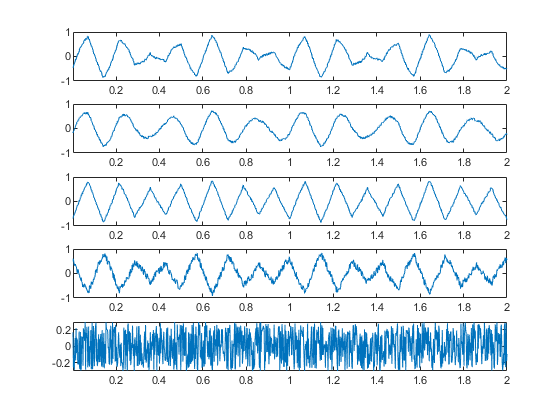

C1 = 0.75*sin(2*pi*freq1*taxis);        % 1st component: a sine wave
C2 = sawtooth(2*pi*freq2*taxis,0.5);    % 2nd component: a triangular wave

% Combine data in different proportions
X(1,:) = 0.5*C1 + 0.5*C2 + 0.1*rand(1,N);
X(2,:) = 0.7*C1 + 0.2*C2 + 0.1*rand(1,N);
X(3,:) = 0.2*C1 + 0.7*C2 + 0.1*rand(1,N);
X(4,:) = -0.3*C1 - 0.6*C2 + 0.3*rand(1,N);
X(5,:) = 0.6*rand(1,N);    % Noise only

% Center data by subtracting mean
X = X - mean(X,2)*ones(1,N);

figure, 
for i=1:size(X,1)
    subplot(size(X,1),1,i)
    plot(taxis,X(i,:)),xlim([taxis(1) taxis(end)])
end

## Independent Components Analysis using FastICA

[icasig, A, W] = fastica(X,'numOfIC',ICNo,'displayMode','off','firstEig',1,'lastEig',PCNo); % fast ICA

Number of signals: 5
Number of samples: 1000
Calculating covariance...
Reducing dimension...
Selected [ 3 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 0.032013 ]
Largest remaining (non-zero) eigenvalue [ 0.541278 ]
Sum of removed eigenvalues [ 0.00590867 ]
[ 99.1112 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 2.77556e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 ......computed ( 6 steps ) 
IC 2 .......computed ( 7 steps ) 
IC 3 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.


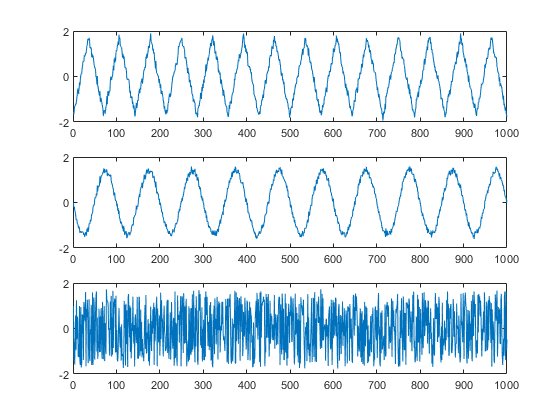


% [icasig, A, W] = fastica(X,'numOfIC',ICNo,'displayMode','off','interactivePCA','on'); % fast ICA
% fasticag(X)  % used the correct number of PCA can always produce good results

figure,
for i=1:size(icasig,1)
    subplot(size(icasig,1),1,i),plot(icasig(i,:))
end


return

## reconstruct signal

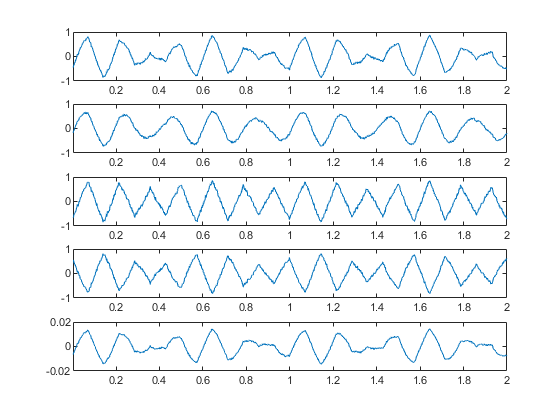

rejectICA=3;
% reconstruct the signal
A2=A;
icasig2=icasig;
A2(:,rejectICA)=[];
icasig2(rejectICA,:)=[];

newX=(A2*icasig2);

figure, 
for i=1:size(newX,1)
    subplot(size(newX,1),1,i)
    plot(taxis,newX(i,:)),xlim([taxis(1) taxis(end)])
end